# Zadatak2 - Kvantizatori

## 2.0 - Snimanje govorne sekvence 

Fs = 8000; 
br_bita = 16;
br_kanala = 1;
audio_rec = audiorecorder(Fs, br_bita, br_kanala);
disp("Zapocnite govor.")

Zapocnite govor.



trajanje_sekvence = 8; 
recordblocking(audio_rec, trajanje_sekvence);
disp("Kraj snimanja.")

Kraj snimanja.



play(audio_rec);
sekvenca = getaudiodata(audio_rec);
fajl = 'govorna_sekvenca.wav';
audiowrite(fajl,sekvenca, Fs)

[sekvenca, Fs] = audioread('govorna_sekvenca.wav');

## 2.1 - Kompaunding kvantizator

Uniformni kvantizator se odlikuje linearnom SNR karakteristikom za različite vrednosti jačine govornog signala. To je u redu ukoliko je potreban jednostavan kvantizator za kvantizaciju signala koji nisu brzo promenljivi ili slabijeg inteziteta. S obzirom da govor uglavnom, gotovo uvek zadovoljava ove problematične uslove, potrebno je dodati popravku na uniformni kvantizator. Moguća su dva rešenja. Prvo, da se adaptivno menja korak kvantizacije, što je slučaj kod optimalnog kvantizatora. Drugo, da se signal transformiše nelinearnom funkcijom, tako da sve vrednosti budu jednako verovatne, tj. približno uniformne. 

Ideja iza kompaunding kvantizatora baš i jeste to, da se korišćenjem funkcije "razvuče" ulazni signal. Teorijski bi to bila logaritamska funkcija, ali s obzirom da logaritamska funkcija ima problema u vrednostima oko nule, koristi se modifikovana funkcija oblika:


$$F\left\lbrack x\right\rbrack =\mathrm{xmax}\;\frac{\log \left(1+\frac{\mu \left|x\right|}{\mathrm{xmax}}\right)}{\log \left(1+\mu \right)}\mathrm{sgn}\left(x\right)$$
 

Teorijski se očekuje SNR koji je gotovo ravna, sporo opadajuća funkcija, pogodna za različite jačine ulaznog signala. Dalje će biti predstavljeni projektovnih 6 kvantizatora sa vrednostima od $\mu =\left\lbrack 100,500\right\rbrack \;i\;{\mathrm{br}}_{\mathrm{bita}} =\left\lbrack 4,8,12\right\rbrack \ldotp$ Jačina ulaznog signala biće modelovanja prostim skaliranjem signala konstantom.

strength_coeffs = 0.05:0.01:1;

odnos_x = [];
maks_x = max(abs(sekvenca));

SNR = zeros(6, length(strength_coeffs));

output = zeros(6, length(sekvenca));

i = 1;
for ni = [100, 500]
    for num_bits = [4, 8, 12]

        SNR_tr = [];
        num_lvls = 2^num_bits;
        delta = 2*maks_x/(2^num_bits);
    
        for a = strength_coeffs
            
            % scaling 
            scaled_x = a*sekvenca;

            % F(x) transformation
            transform_x = (maks_x*(log10(1 + ni*abs(scaled_x)/maks_x))/log10(1 + ni)).*sign(scaled_x);   

            % Uniform kvantizer - implicitly defined positive and
            % negativne values in F(X), beacuse of the sgn(X) function

            uniform_x = round(transform_x/delta) * delta;
       
            
            %edge case
            unifrom_x(scaled_x > (num_lvls -1)*delta) = (num_lvls/2 - 1)*delta;


            % F(x)^-1 transformation

            inv_transform_x = 1/ni*sign(uniform_x).*((i+ni).^(abs(uniform_x)/maks_x)-1)*maks_x;
            
            % SNR calculation
            SNR_tr = [SNR_tr 10*log10(var(scaled_x)/var(scaled_x-inv_transform_x))];
            
            if i == 1
            % xmax/sigmax calculation
                odnos_x = [odnos_x maks_x/sqrt(var(scaled_x))];
            end
        end

        output(i,:) = inv_transform_x;
        SNR(i,:) = SNR_tr;
        i = i + 1;
    end
end

Gledajući dobijene rezultate možemo videti potvrdu teorijskih očekivanja. Povećanjem broja bita, povećava se i SNR, tj karakteristika se translira na gore. Variranjem $\mu$ parametra se izravanjava karakteristika samog kvantizatora, tako da je SNR konstantniji za sve moguće jačine govora. Dešava se anomalija u rezultatima za broj bita, da eksperiment ne potvrđuje teorijski očekivane rezultate za izgled krive.

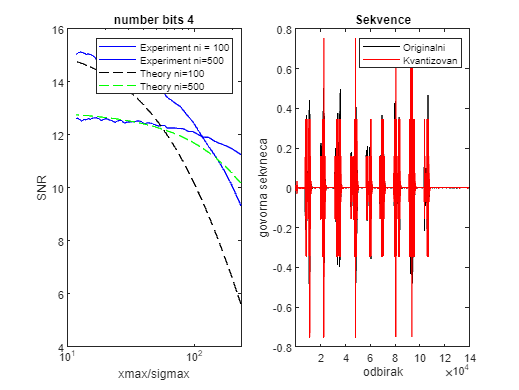

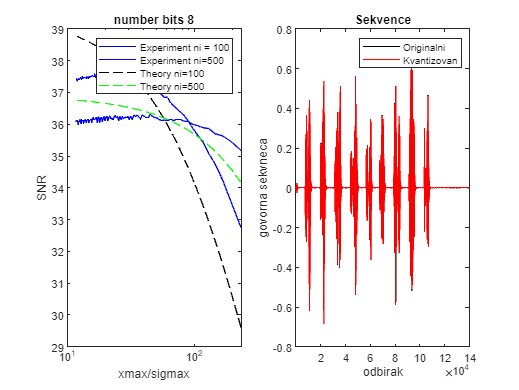

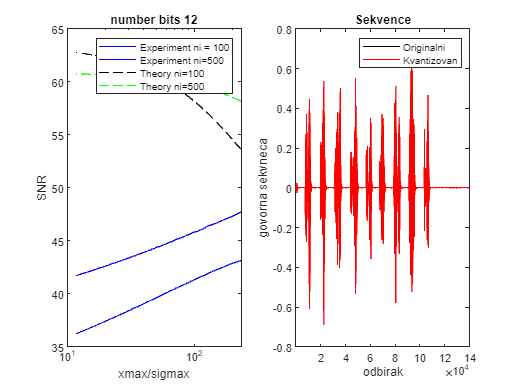

bits = [4, 8, 12];
len = length(sekvenca);
nis = [100,500];

for j = 1:3
    
    bit = bits(j);
 
    SNR_theory_100 = SNR_func(nis(1),odnos_x,bit);
    SNR_theory_500 = SNR_func(nis(2),odnos_x,bit);
    
    fig = figure(j);
        subplot(1,2,1);
            semilogx(odnos_x, SNR(j,:),'b');
            hold on
                semilogx(odnos_x,SNR(j+3,:), 'b');
                semilogx(odnos_x,SNR_theory_100, 'k--');
                semilogx(odnos_x,SNR_theory_500, 'g--');
           hold off;
           legend('Experiment ni = 100', 'Experiment ni=500', 'Theory ni=100', 'Theory ni=500');
           title('number bits ' + string(bit));
           xlabel('xmax/sigmax');
           ylabel('SNR');
       subplot(1,2,2);
           plot(1:140001, sekvenca(20000:160000), 'k')
           hold on
                plot(1:140001, output(j+3, 20000:160000), 'r')
           hold off;
           title("Sekvence")
           xlim([1 140001])
           xlabel('odbirak')
           ylabel('govorna sekvneca')
           legend('Originalni','Kvantizovan')
           
end

## 2.2 - Delta kvantizator

Delta kvantizator je vrsta kvantizatora koji na izlazu povećava ili smanjuje prethodni izlaz kvantizatora za određeni delta priraštaj. Ovaj estimator estimira koeficijent pravca samog ulaznog govornog signala; ukoliko je pozitivan, dodaje se na prethodnu vrednost signala $+\Delta$, ukoliko je negativan $-\Delta$. U svrhu estimacije se koristi vrlo prosti prediktor $\alpha z^{-1}$, drugim rečima, uzima se prethodna vrednost izlaza, množi sa nekom konstantom i oduzima od trenutne vrednosti signala. Na taj način se uvodi memorija što dovodi do mogućnosti da izlazna kvantizovana vrednost signala prati ulaznu funkciju.

U zavisnosti veličine parametra $\Delta$, mogu se desiti dva nepogodna granična slučaja:

- Slope overcharge - premalo $\Delta$. Dešava se da kvantizator ne može sa sukcesivnim dodavanjem $\Delta$, da dositgne rast ulazne funkcije govora.

- Granular noise - preveliko $\Delta$. Male promene u ulaznom signalu, izazivaju velike promene na izlazu kvantizatora, kvantizator ne poseduje mogućnost da izvuče informaciju manje intezivnih i brzopromenljivih signala.

Dalje su predstavljena oba granična slučaja, estimacija optimalnog $\Delta$ sa histogramom, kao i slučaj kada je iskorišćen estimirani $\Delta$ parametar.

### Slope overcharge

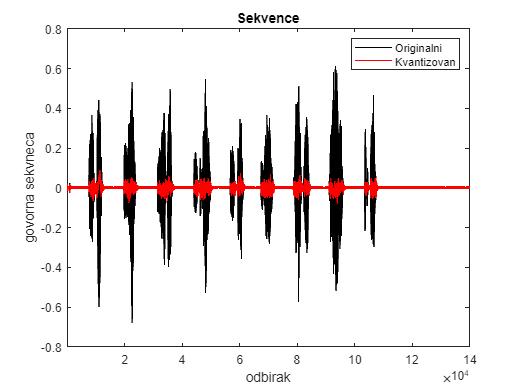


len = length(sekvenca);
delta = 0.005;
alpha = 1;
mean_val = mean(sekvenca);

increments = zeros(1, len);
increments(1) = sekvenca(1);

kvant_increments = zeros(1,len);

output = zeros(1,len);
output(1) = kvant_increments(1) + mean_val;

for i = 2:len
    increments(i) = sekvenca(i) - alpha*output(i-1);
    if increments(i) > 0
        kvant_increments(i) = delta;
    else 
        kvant_increments(i) = -delta;
    end
    
    output(i) = alpha*output(i-1) + kvant_increments(i);
end

fig = figure();
plot(1:140001, sekvenca(20000:160000), 'k')
    hold on
       plot(1:140001, output(20000:160000), 'r')
    hold off;
    title("Sekvence")
    xlim([1 140001])
    xlabel('odbirak')
    ylabel('govorna sekvneca')
    legend('Originalni','Kvantizovan')

### Granular noise

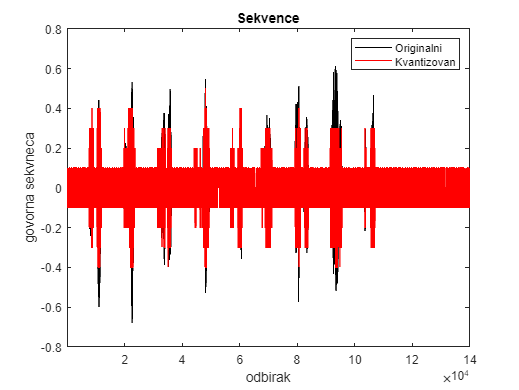

len = length(sekvenca);
delta = 0.1;
alpha = 1;
mean_val = mean(sekvenca);

increments = zeros(1, len);
increments(1) = sekvenca(1);

kvant_increments = zeros(1,len);

output = zeros(1,len);
output(1) = kvant_increments(1) + mean_val;

for i = 2:len
    increments(i) = sekvenca(i) - alpha*output(i-1);
    if increments(i) > 0
        kvant_increments(i) = delta;
    else 
        kvant_increments(i) = -delta;
    end
    
    output(i) = alpha*output(i-1) + kvant_increments(i);
end

fig = figure();
plot(1:140001, sekvenca(20000:160000), 'k')
    hold on
       plot(1:140001, output(20000:160000), 'r')
    hold off;
    title("Sekvence")
    xlim([1 140001])
    xlabel('odbirak')
    ylabel('govorna sekvneca')
    legend('Originalni','Kvantizovan')

### Histogram

Za optimalan parametar delta uzeće se standardn devijacija ulaznog signala, s obzirom da je očekivana teorijska raspodela laplasova, sto se vidi na dobijenom histogramu. Histogram se formira na osnovu vrednosti priraštaja samog signala.

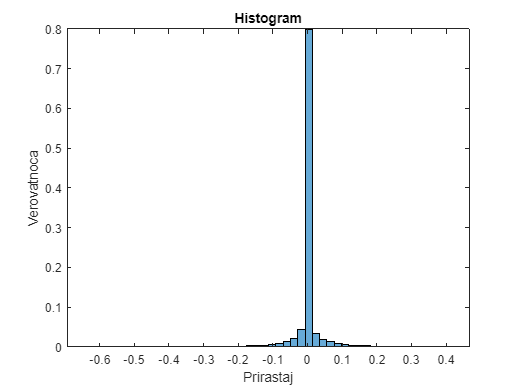

buckets = 50;
increments = sekvenca(1:end-1) - sekvenca(2:end);
fig = figure();
    histogram(increments, buckets, 'Normalization','probability');
    title('Histogram');
    xlabel('Prirastaj');
    ylabel('Verovatnoca');


mean_val = mean(increments); 
delta_opt = sqrt(var(increments))

delta_opt = 0.0387

## Optimalan delta kvantizator

Dobijen je solidan rezultat u kvantizaciji, ali ovaj metod nije povoljan iy dva razloga:

- Šumovitost izaziva veće oscilacije na izlazu kvantizatora

- Radi smanjenja granularnog šuma, kvantizator ne može da isprati do kraja signale sa promenama velikog intenziteta.

Poboljšanja postoje u vidu adaptivnih kvantizatora, sa promenljivim korakom kvantizacije.

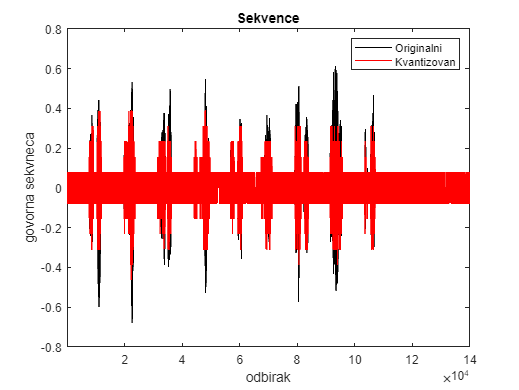

len = length(sekvenca);
delta = delta_opt;
alpha = 1;
mean_val = mean(sekvenca);

increments = zeros(1, len);
increments(1) = sekvenca(1);

kvant_increments = zeros(1,len);

output = zeros(1,len);
output(1) = kvant_increments(1) + mean_val;

for i = 2:len
    increments(i) = sekvenca(i) - alpha*output(i-1);
    if increments(i) > 0
        kvant_increments(i) = delta;
    else 
        kvant_increments(i) = -delta;
    end
    
    output(i) = alpha*output(i-1) + kvant_increments(i);
end

fig = figure();
plot(1:140001, sekvenca(20000:160000), 'k')
    hold on
       plot(1:140001, output(20000:160000), 'r')
    hold off;
    title("Sekvence")
    xlim([1 140001])
    xlabel('odbirak')
    ylabel('govorna sekvneca')
    legend('Originalni','Kvantizovan')